## Тест 1

a = -1;
b = 1;
alpha = [1 0];
beta = [1 0];
syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
p(x) = 1/(2+x);
q(x) = sin(x);
f(x) = 1+x;
v(x) = vpa(0);
n = 4;
Du = diff(u);

Решаем следующий дифур:

-diff(p*diff(u)) +v*diff(u)+q*u == f

$$ans(x) = \sin\left(x\right)\,u\left(x\right)+\frac{\frac{\partial }{\partial x}u\left(x\right)}{{\left(x+2\right)}^{2}}-\frac{\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)}{x+2}=x+1$$

Краевые условия:

alpha(1)*u(a)-alpha(2)*Du(a) == 0

$$ans = u\left(-1\right)=0$$

beta(1)*u(b)+beta(2)*Du(b) == 0

$$ans = u\left(1\right)=0$$

Точное решение:

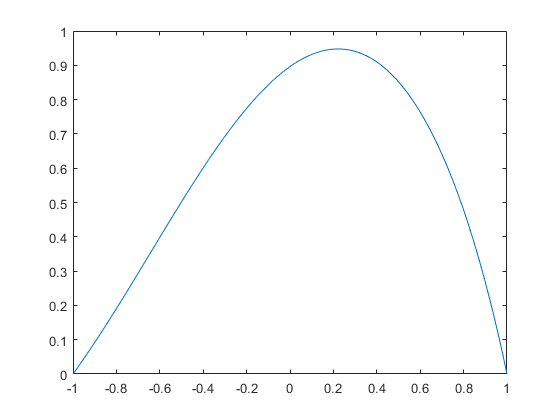

dp = diff(p);
fun = @(x,y) [y(2); (((v(x)-dp(x))/p(x))*y(2)+(q(x)/p(x))*y(1)-f(x)/p(x))];
bc = @(ya, yb) [ya(1); yb(1)];
xmesh = linspace(-1, 1, 100);
solinit = bvpinit(xmesh, [0 1]);
sol = bvp4c(fun, bc, solinit);
plot(sol.x,sol.y(1,:));

Численное решение методом Ритца:

y_1= ritz(a,b,alpha,beta, n, p, q, f);
y_1 = simplify(y_1)

$$y\_1 = -1.463\,x^{3}+0.08103\,x^{2}+4.181\,x-3.639$$

График полученного решения:

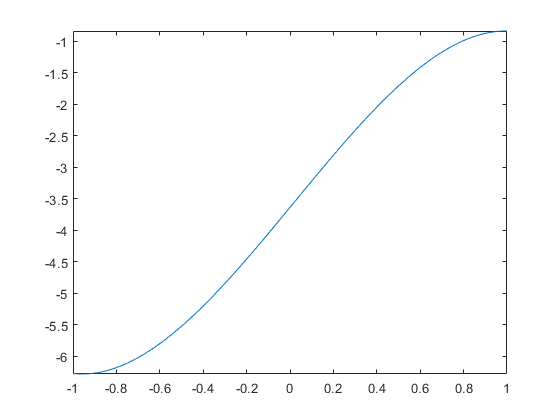

fplot(y_1, [a,b]);

d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));

Максимальная погрешность:

max(abs(d_1))

ans =    6.376603361959842


График погрешности:

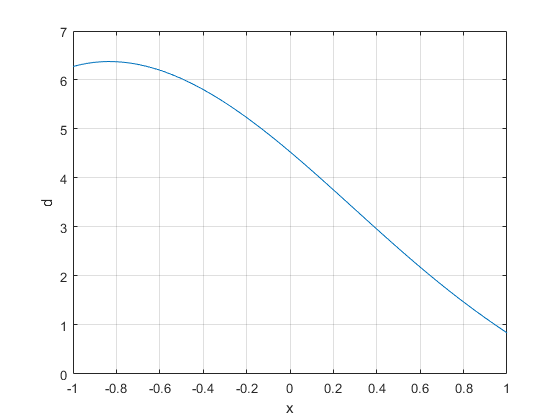

plot(sol.x, d_1);
xlabel('x');
ylabel('d');
grid;

Численное решение методом коллакаций:

y_2 = coloc(a,b,n, p, q, f, v);
y_2 = simplify(y_2)

$$y\_2 = -0.09138\,x^{5}-0.1061\,x^{4}-0.3494\,x^{3}-0.768\,x^{2}+0.4408\,x+0.8741$$

График полученного решения:

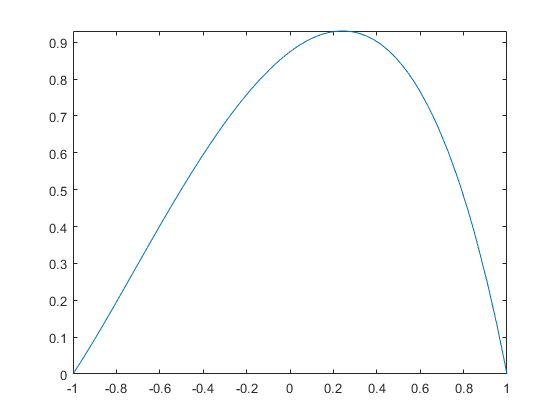

fplot(y_2, [a,b]);

d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));

Максимальная погрешность:

max(abs(d_2))

ans =    0.022312034069809


График погрешности:

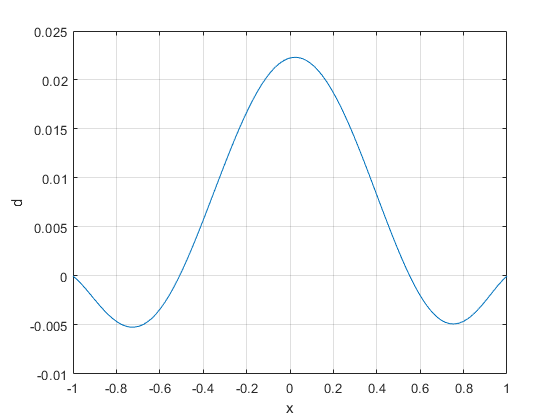

plot(sol.x, d_2);
xlabel('x');
ylabel('d');
grid;

## Тест 2

a = -1;
b = 1;
alpha = [0 -1];
beta = [1 1];
syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
p(x) = (2+x)/(3+x);
q(x) = 1 + sin(x);
f(x) = 1-x;
v(x) = vpa(0);
n = 4;
Du = diff(u);

Решаем следующий дифур:

-diff(p*diff(u)) +v*diff(u)+q*u == f

$$ans(x) = u\left(x\right)\,\left(\sin\left(x\right)+1\right)-\frac{\frac{\partial }{\partial x}u\left(x\right)}{x+3}+\frac{\left(x+2\right)\,\frac{\partial }{\partial x}u\left(x\right)}{{\left(x+3\right)}^{2}}-\frac{\left(x+2\right)\,\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)}{x+3}=1-x$$

Краевые условия:

alpha(1)*u(a)-alpha(2)*Du(a) == 0

$$ans = \left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=-1}\right)=0$$

beta(1)*u(b)+beta(2)*Du(b) == 0

$$ans = u\left(1\right)+\left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=1}\right)=0$$

Точное решение:

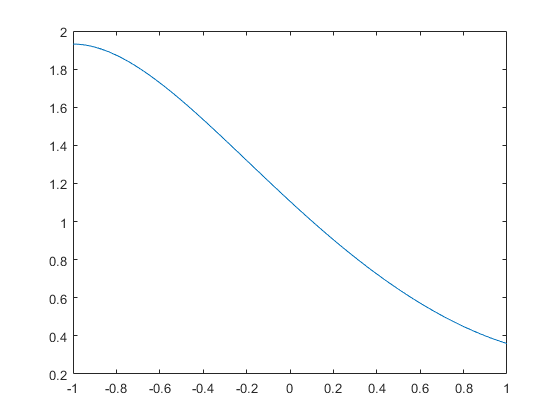

dp = diff(p);
fun = @(x,y) [y(2); -(((dp(x)-v(x))/p(x))*y(2)-(q(x)/p(x))*y(1)+f(x)/p(x))];
bc = @(ya, yb) [ya(2); yb(2)+yb(1)];
xmesh = linspace(-1, 1, 100);
solinit = bvpinit(xmesh, [0 1]);
sol = bvp4c(fun, bc, solinit);
plot(sol.x,sol.y(1,:));

Численное решение методом Ритца:

y_1= ritz(a,b,alpha,beta, n, p, q, f);
y_1 = simplify(y_1)

$$y\_1 = 0.2698\,x^{3}+0.01837\,x^{2}-1.055\,x+1.128$$

График полученного решения:

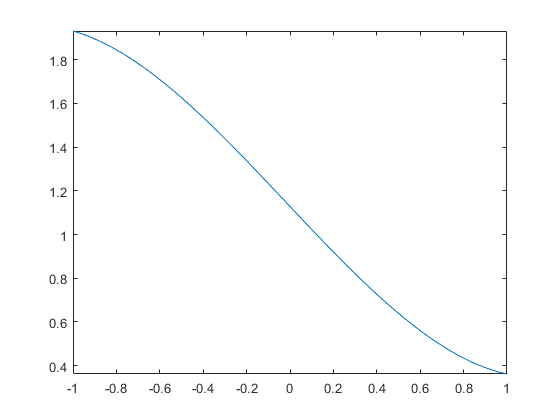

fplot(y_1, [a,b]);

d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));

Максимальная погрешность:

max(abs(d_1))

ans =    0.027609313468769


График погрешности:

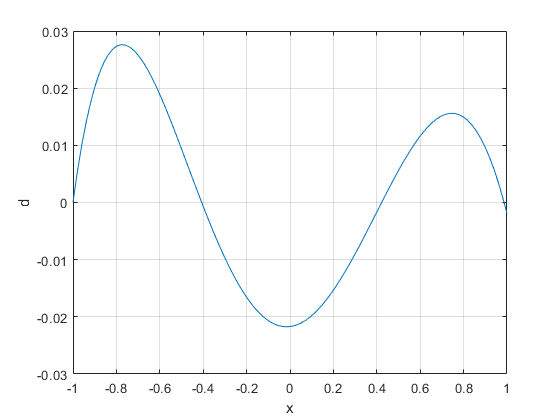

plot(sol.x, d_1);
xlabel('x');
ylabel('d');
grid;

Численное решение методом коллакаций:

y_2 = coloc(a,b,n, p, q, f, v);
y_2 = simplify(y_2)

$$y\_2 = 0.03007\,x^{5}-0.1459\,x^{4}+0.3152\,x^{3}-0.3438\,x^{2}-0.3452\,x+0.4897$$

График полученного решения:

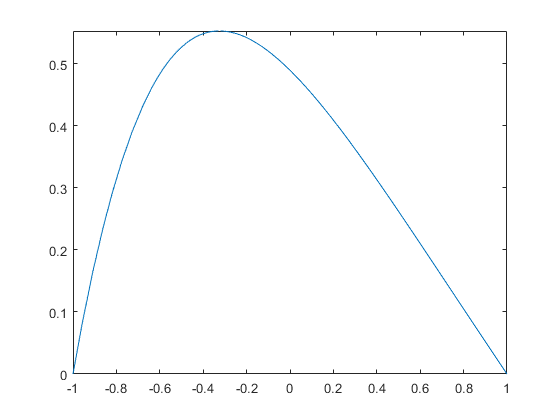

fplot(y_2, [a,b]);

d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));

Максимальная погрешность:

max(abs(d_2))

ans =    1.931432799373040


График погрешности:

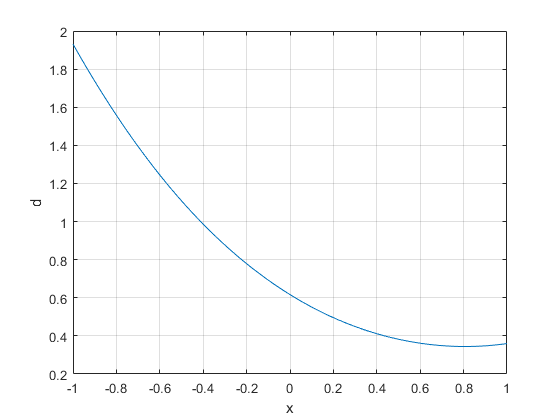

plot(sol.x, d_2);
xlabel('x');
ylabel('d');
grid;

% %тест3
% a = -1;
% b = 1;
% alpha = [1 -1];
% beta = [0 1];
% syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
% p(x) = 2/(2+x);
% q(x) = cos(x/2);
% f(x) = 1+x/2;
% v(x) = vpa(0);
% n = 4;
% Du = diff(u);
% %Решаем следующий дифур:
% -diff(p*diff(u)) +v*diff(u)+q*u == f
% %Краевые условия:
% alpha(1)*u(a)-alpha(2)*Du(a) == 0
% beta(1)*u(b)+beta(2)*Du(b) == 0
% %Точное решение:
% dp = diff(p);
% fun = @(x,y) [y(2); -(((dp(x)-v(x))/p(x))*y(2)-(q(x)/p(x))*y(1)+f(x)/p(x))];
% bc = @(ya, yb) [ya(2); yb(2)+yb(1)];
% xmesh = linspace(-1, 1, 100);
% solinit = bvpinit(xmesh, [0 1]);
% sol = bvp4c(fun, bc, solinit);
% plot(sol.x,sol.y(1,:));
% % Численное решение методом Ритца:
% y_1= ritz(a,b,alpha,beta, n, p, q, f);
% y_1 = simplify(y_1)
% %График полученного решения:
% fplot(y_1, [a,b]);
% d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));
% %Максимальная погрешность:
% max(abs(d_1))
% %График погрешности:
% plot(sol.x, d_1);
% xlabel('x');
% ylabel('d');
% grid;
% %Численное решение методом коллакаций:
% y_2 = coloc(a,b,n, p, q, f, v);
% y_2 = simplify(y_2)
% %График полученного решения:
% fplot(y_2, [a,b]);
% d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));
% %максимальная погрешность:
% max(abs(d_2))
% %График погрешности:
% plot(sol.x, d_2);
% xlabel('x');
% ylabel('d');
% grid;
